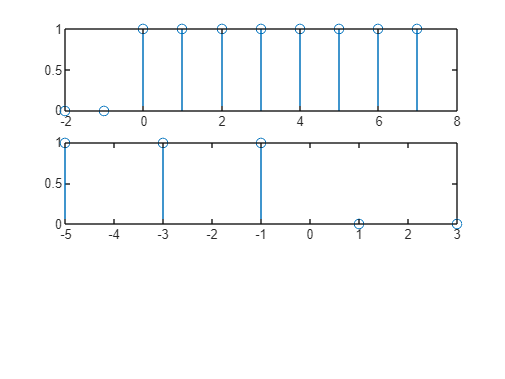

clc;
clear all;
close all;

t1=input("enter the time range :");
a1=input("enter the amplitude :");

[y1]=stepwv(a1,t1);

subplot(3,1,1);
stem(t1,y1);


t2=input("enter the time range :");
a2=input("enter the amplitude :");

y2=a2*(t2<=0);

subplot(3,1,2);
stem(t2,y2);


t3=min(min(t1),min(t2)):min(t1(2)-t1(1),t2(2)-t2(1)):max(max(t1),max(t2));

%y0=[];
%temp=1;
%for i=1:length(t3)
    %if(t3(i)<min(t1) || t3(i)>max(t1))
     %   y0=[y0 0];
    %else
   %     y0=[y0 y1(temp)];
  %      temp=temp+1;
 %   end
%end
y0=[];
temp=1;
for i=1:length(t3)
    for j=1:length(t2)
        if(t3(i)==t2(j))
             y0=[y0 y2(temp)];
             temp=temp+1;
       
        end
    end
     y0=[y0 0];
end    
y4=[];
temp=1;
for i=1:length(t3)
    for j=1:length(t1)
        if(t3(i)==t1(j))
             y4=[y4 y1(temp)];
             temp=temp+1;
       
        end 
             
    end
     y4=[y4 0];
end    

%y4=[];
%temp=1;
%for i=1:length(t3)
   % if(t3(i)<min(t2) || t3(i)>max(t2))
     %   y4=[y4 0];
    %else
   %     y4=[y4 y2(temp)];
  %      temp=temp+1;
 %   end
%end

y3=y0+y4;

Arrays have incompatible sizes for this operation.

Related documentation


subplot(3,1,3);
stem(t3,y3);

